# **Homework 2**

**Question 2: Simulation of dynamic systems**

Consider the dynamic system defined as,


$$\bf{\ddot{x} + 4\dot{x} + 3x = u}$$


- Express the dynamics of the system in state space form and compute the eigen values of the system dynamics matrix. What can you say about the stability properties of the system.

- Using $\bf{u = 0}

$, and assuming you start at $\bf{x = 1}$ and $\bf{\dot{x} = 0}$, numerically solve the the system dynamics equation using euler difference method, runge-kutta 4 with fixed time-step, and ode45. For fixed time-step, choose $\bf{dt = 0.1 $and total time of **10s**.

- Compare the solutions obtained from euler difference method, runge-kutta 4 with fixed time-step and ode45 to the analytical solution.

- Compare the solutions obtained from euler difference method, runge-kutta 4 with fixed time-step and ode45 to the analytical solution, for  $\bf{dt = 0.5}$, $\bf{dt = 0.1}$and $\bf{dt = 0.2}$ and simulate for total time of **10s**. What are the advantages and disadvantages of choosing a smaller or larger **dt** values?

- Based on results above, which numerical integration scheme will you recommend?

## Solution

clc
close all
clear all


Let: 


$$\bf{x_1 = x}$$


  
$$\bf{x_2 = \dot{x}_1$$



$$\bf{x_3 = \dot{x}_2 = -4x_2 - 3x_1 + u$$


So in state-space we have 


$$\bf{\dot{X} = \pmatrix{0& 1 \cr -3&-4 }X + \pmatrix{0\cr1}u$$


A = [0 1;-3 -4];
B = [0;1];

[V, D] = eig(A)

V =     0.7071   -0.3162
   -0.7071    0.9487


D =     -1     0
     0    -3


Since the eigenvalues of the system are both negative, this system will converge to 0 and is stable.

With u = 0, time step = 0.1s and total time = 10s we have:

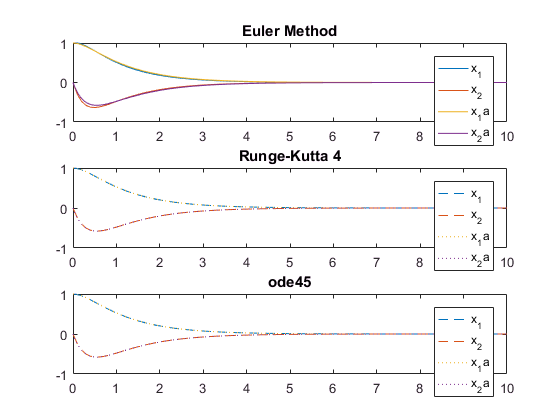

sys_dyn = @(t,x)[A*x];
dt = 0.1;
Tspan = 10;
x0 = [1;0];

[t,x] = myEuler(sys_dyn, dt, Tspan, x0);

%Analytical solution of position and velocity using
% x = A*exp(-(gamma/2 + beta)*t) + B*exp(-(gamma/2 - beta)*t)
% and solving for A and B using intial conditions for x and dx/dt
% where beta = (4^2/4 - 3)^(1/2) = 1 and gamma = 4
analytical_X = @(ta)[-0.5*exp(-3*ta) + 1.5*exp(-ta)]; 
analytical_dX = @(ta)[1.5*exp(-3*ta) - 1.5*exp(-ta)];


%XofT = @(ta)[x0*expm(ta*A)];



figure;
subplot(3,1,1);
plot(t,x)
hold on
syms ta
fplot(analytical_X(ta),  [0 10])
hold on
fplot(analytical_dX(ta), [0 10])
legend('x_1','x_2','x_1a','x_2a')
title(['Euler Method'])


[t,x] = myRungeKutta4(sys_dyn, dt, Tspan, x0);


subplot(3,1,2);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10],':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['Runge-Kutta 4'])

Tspan = 0:0.1:10;
[t,x] = ode45(sys_dyn, Tspan, x0);
subplot(3,1,3);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10],':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['ode45'])

We can see clearly from above that the Euler Method presents more error. Runge-Kutta 4 and ode45 appear to be identical to the analytical solution.

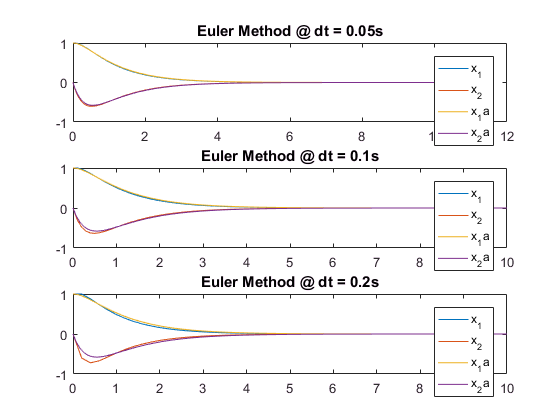

Tspan = 10;
dt = 0.05;
[t,x] = myEuler(sys_dyn, dt, Tspan, x0);
figure;
subplot(3,1,1);
plot(t,x)
hold on
syms ta
fplot(analytical_X(ta),  [0 10])
hold on
fplot(analytical_dX(ta), [0 10])
legend('x_1','x_2','x_1a','x_2a')
title(['Euler Method @ dt = 0.05s'])

dt = 0.1;
[t,x] = myEuler(sys_dyn, dt, Tspan, x0);
subplot(3,1,2);
plot(t,x)
hold on
syms ta
fplot(analytical_X(ta),  [0 10])
hold on
fplot(analytical_dX(ta), [0 10])
legend('x_1','x_2','x_1a','x_2a')
title(['Euler Method @ dt = 0.1s'])

dt = 0.2;
[t,x] = myEuler(sys_dyn, dt, Tspan, x0);
subplot(3,1,3);
plot(t,x)
hold on
syms ta
fplot(analytical_X(ta),  [0 10])
hold on
fplot(analytical_dX(ta), [0 10])
legend('x_1','x_2','x_1a','x_2a')
title(['Euler Method @ dt = 0.2s'])

Above we can see the numerical solution becoming more and more accurate with decreasing time-step.

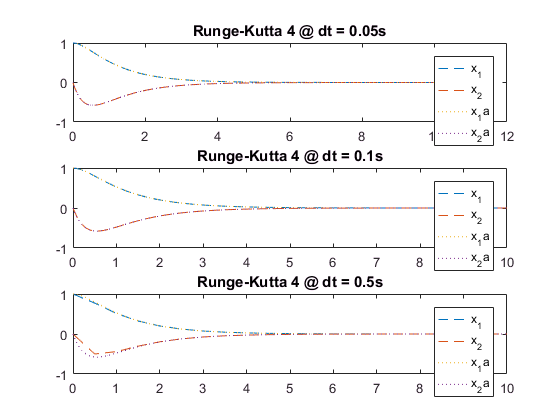

Tspan = 10;
dt = 0.05;
[t,x] = myRungeKutta4(sys_dyn, dt, Tspan, x0);
figure;
subplot(3,1,1);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10],':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['Runge-Kutta 4 @ dt = 0.05s'])

dt = 0.1;
[t,x] = myRungeKutta4(sys_dyn, dt, Tspan, x0);
subplot(3,1,2);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10],':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['Runge-Kutta 4 @ dt = 0.1s'])

dt = 0.5;
[t,x] = myRungeKutta4(sys_dyn, dt, Tspan, x0);
subplot(3,1,3);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10], ':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['Runge-Kutta 4 @ dt = 0.5s'])

For the Runge--Kutta 4, a much larger time-step is required to see a noticeable difference.

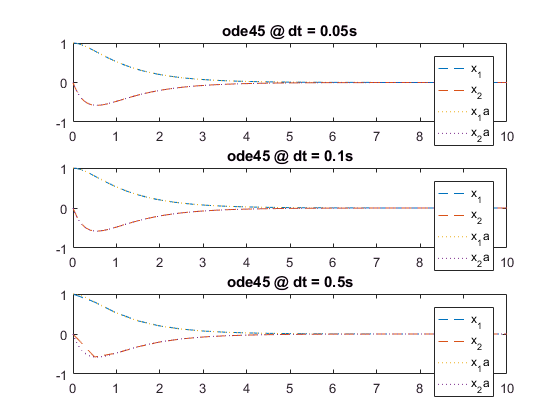

Tspan = 0:0.05:10;
[t,x] = ode45(sys_dyn, Tspan, x0);
figure;
subplot(3,1,1);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10],':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['ode45 @ dt = 0.05s'])

Tspan = 0:0.1:10;
[t,x] = ode45(sys_dyn,Tspan, x0);
subplot(3,1,2);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10],':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['ode45 @ dt = 0.1s'])

Tspan = 0:0.5:10;
[t,x] = ode45(sys_dyn,Tspan, x0);
subplot(3,1,3);
plot(t,x,'--')
hold on
syms ta
fplot(analytical_X(ta),  [0 10], ':')
hold on
fplot(analytical_dX(ta), [0 10],':')
legend('x_1','x_2','x_1a','x_2a')
title(['ode45 @ dt = 0.5s'])

Above we can see that ode45 is the most accurate. Although difficult to see, the error around .5s for $x_2$ is  more pronounced for the Runge-Kutta 4 method. Based on these results I would definitely use ode45 for a numerical solution as it will be more forgiving if my chosen time step is too large. 